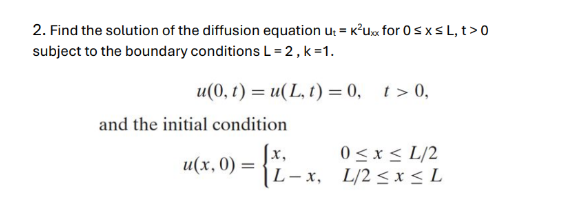

clearvars;clf;clc;
% Parameters
L = 2; 
k = 1; 
x = linspace(0, L, 100);
t = linspace(0, 1, 200);
% Initial condition
u0 = zeros(size(x));
u0(x <= L/2) = x(x <= L/2);
u0(x > L/2) = L - x(x > L/2);

N = 50

N = 50


% Initialize u(x,t)
u_xt = zeros(length(x), length(t));

**Fourier series solution**

for n = 1:N
    lambda_n = n * pi / L; 
    Bn = (2 / L) * trapz(x, u0 .* sin(lambda_n * x)); % Fourier coefficient
    for j = 1:length(t)
        u_xt(:, j) = u_xt(:, j) + Bn * sin(lambda_n * x') .* exp(-k^2 * lambda_n^2 * t(j));
    end
end

**Plot graph 3D**

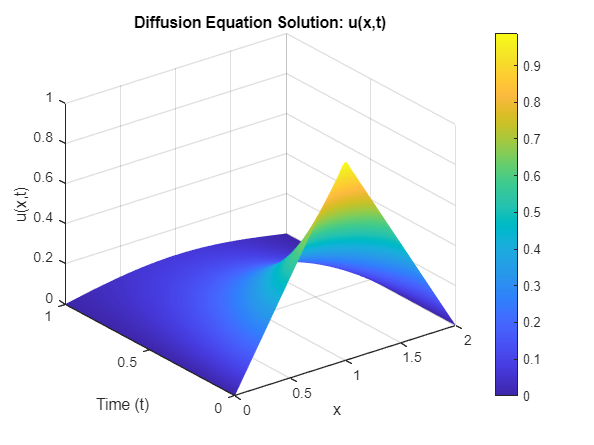

figure;
[X, T] = meshgrid(x, t);
surf(X, T, u_xt');
shading interp;
title('Diffusion Equation Solution: u(x,t)');
xlabel('x');
ylabel('Time (t)');
zlabel('u(x,t)');
colorbar;
grid on;

**Plot u(x,t) at different time instants**

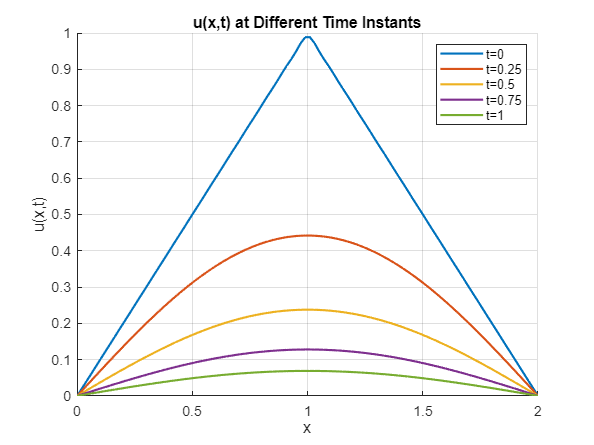

figure;
hold on;
for t_idx = [1, 50, 100, 150, 200]
    plot(x, u_xt(:, t_idx), 'LineWidth', 1.5);
end
title('u(x,t) at Different Time Instants');
xlabel('x');
ylabel('u(x,t)');
legend('t=0', 't=0.25', 't=0.5', 't=0.75', 't=1');
grid on;